### **Método do Ponto Fixo****  (MPF)**


$$x^{k+1} = \Phi(x^{k})$$


onde $\Phi$ é nossa função de iteração de ponto fixo. 

Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o MPF, com $\Phi_{1}(x) = \frac{0.5x^{2}-4.5}{2.5}$ e $\Phi_{2}(x) =\sqrt{ \frac{-2.5x-4.5}{2.5}}$, da  com erro relativo igual ou menor que $10^{-4}$. Uso o chute inicial $x^{0} = -1$.

**Graficamente, **

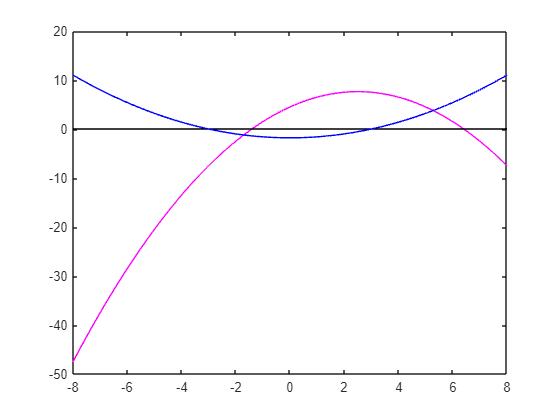

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
phi1 = fun_iteracao(x);
plot(x,phi1, 'blue')
hold off

**Implementação do MPF:**

format long
x0 = -1; %chute inicial 
tol = 10^-4;
k = 0;
er_real = 10; % erro relativo inicial 
while (er_real > tol)
    k=k+1;
    x=(0.5*x0.^2 - 4.5)/2.5; %Atualização pela unção de interação de Ponto Fixo 
    er_real=abs(x-x0)/abs(x);
    x0=x;
end 

fprintf("0 valor da aproximação para zero da função é x = %f", x)

0 valor da aproximação para zero da função é x = -1.405089

**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
function g1 = fun_iteracao(x)
    g1 = (0.5*x.^2 - 4.5)/2.5;
end